**AVD Group 01**

Hanchen Li

Please see **report** for theory and explaination, be aware of the **units** in angle

% House Keeping
clear
clc
close all

g = 9.80665;                          % Standard acceleration of gravity (m/s^2)

Input parameter form Weight and Balance Estimation code

% aftmost CG location (m)
x_ac_aft = 35.4946;
z_ac_aft = -0.3204;
x_ac_aft_down = 35.1987;
z_ac_aft_down = -0.7486;

x_ac_for = 34.7946;
z_ac_for = -0.4058;
x_ac_for_down = 34.8126;
z_ac_for_down = -1.2236;

## **1. Neutral Point**

**Find fuselage coefficient of pitching moment**

x_w_l = 33.2;           % Distance between nosetip to leading edge (m)

x_c_4 = x_w_l + 3.5206; % Wing-root 1/4 chord position (m) % Undefined

L_f = 75.5;             % Total fuselage length (m)

% Find K_f via NACA TR 177

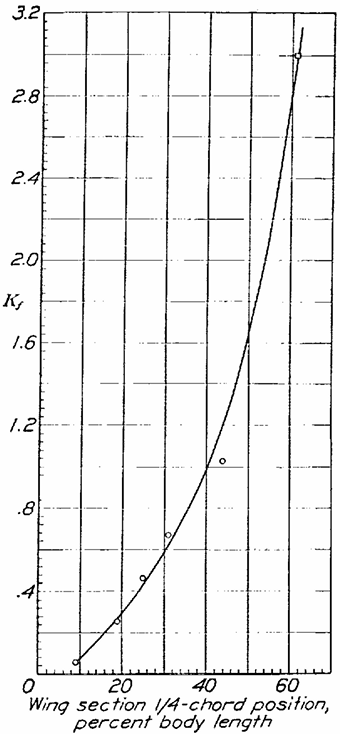


x_c_4 / L_f

ans = 0.4864


K_f = 1.52;          % Undefined

w_f = 6.88;          % Fuselage maximum width (m)

c = 9.84;            % Mean chord length (m) % Undefined

S_w = 639.23;        % Reference wing area (m^2)

d_CM_f = K_f * (L_f * (w_f ^ 2)) / (c * S_w) % (1/rad)

d_CM_f = 0.8636

**Find wing's zero lift pitching moment**

AR = 6.61;              % Aspect Ratio

Sweep = 26.75;          % Wing quarter chord sweep (degree)
Sweep = deg2rad(Sweep); % Wing quarter chord sweep (rad)

twist = 3.9;            % Wing twist (degree)

i_w = -0.1849;          % Wing setting angle (degree)
i_w = deg2rad(i_w);     % Wing setting angle (rad)

C_m_airf_0 = -0.13;     % Incompressible airfoil zero lift pitching moment

d_CL_w_0 = 3.228;       % Incompressible wing lift curve slope (1/rad) % Undefined

% Wing's zero lift pitching moment 'coefficient'
k_C_m0_w = (C_m_airf_0 * (AR * (cos(Sweep) ^ 2)) / (AR + 2 * cos(Sweep)) - 0.01 * twist) / d_CL_w_0

k_C_m0_w = -0.0374

**Other input parameters**

n_h = 0.9;                % Tail efficiency factor

B_w = 64.99;              % Wing span (m)

Taper = 0.20;             % Wing taper ratio

x_ac_w_0 = x_w_l + 11.34; % Wing aerodynamic center at M=0 (m)

x_ac_h_0 = 72.2;          % Wing aerodynamic center at M=0 (m)

h_h = 5.3;                % Vertical distance between wing and horizontal tailplane chord (m)

l_h = x_ac_h_0 - x_ac_w_0; % (m)

S_h = 87.20;              % Horizontal tailplane area (m^2)


Notice $Z_t$ is $+\textrm{ve}$ if thrustline under CG

Z_t = -3.3;              % Thrustline above datum (m)

**Find compressible effect on aerodynamic center**

x_ac_M

% x_ac = x_ac_M(x_ac_0, M, S_wing)

**Find downwash derivative**

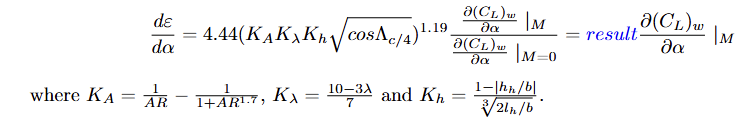

K_A = 1 / AR - 1 / (1 + AR ^ 1.7);

K_Taper = (10 - 3 * Taper) / 7;

K_h = (1 - abs(h_h / B_w)) / ((2 * l_h / B_w) ^ (1 / 3));

% Downwash derivative 'coefficient'
k_d_downwash = (4.44 * (K_A * K_Taper * K_h * (cos(Sweep)) ^ 0.5) ^ 1.19) / d_CL_w_0

k_d_downwash = 0.1307

results


$$x_{\textrm{np}} =\frac{\frac{{d\left(C_L \right)}_W }{d\alpha }{\left(x_{\textrm{ac}} \right)}_w -\frac{{\delta \left(C_M \right)}_f }{\delta \alpha }\bar{c} +\eta_h \frac{{d\left(C_L \right)}_h }{d\alpha }\left(1-\frac{d\varepsilon }{d\alpha }\right)\frac{S_h }{S_w }{\left(x_{\textrm{ac}} \right)}_h }{\frac{{d\left(C_L \right)}_W }{d\alpha }+\eta_h \frac{{d\left(C_L \right)}_h }{d\alpha }\left(1-\frac{d\varepsilon }{d\alpha }\right)\frac{S_h }{S_w }}$$


**0-1** Takeoff **&** **4-5** Missed approach

%a_0_w_TO = -0.8848;  % Wing takeoff zero lift angle of attack (rad)
%d_CL_w_TO = 3.4049;  % Wing takeoff lift curve slope (1/rad)

%a_0_h_TO = -0.0204;  % Horizontal tailplane takeoff zero lift angle of attack (rad)
%d_CL_h_TO = 0.2428;  % Horizontal tailplane takeoff lift curve slope (1/rad)

a_0_w_TO = -0.113;  % Wing 1st cruise zero lift angle of attack (rad)
d_CL_w_TO = 5.5;  % Wing 1st cruise lift curve slope (1/rad)

a_0_h_TO = -0.0204;  % Horizontal tailplane 1st cruise zero lift angle of attack (rad)
d_CL_h_TO = 0.2428;  % Horizontal tailplane 1st cruise lift curve slope (1/rad)

CD_TO = 0;           % Takeoff drag coefficient

% No compressibility effect 
x_ac_w_TO = x_ac_w_0

x_ac_w_TO = 44.5400

x_ac_h_TO = x_ac_h_0

x_ac_h_TO = 72.2000


d_downwash_TO = k_d_downwash * d_CL_w_0

d_downwash_TO = 0.4219


C_m0_w_TO = k_C_m0_w * d_CL_w_0

C_m0_w_TO = -0.1206


% Find neutral point
x_np_TO = (d_CL_w_TO * x_ac_w_TO - d_CM_f * c + n_h * d_CL_h_TO * (1 - d_downwash_TO) * (S_h / S_w) * x_ac_h_TO) / ...
    ((d_CL_w_TO + n_h * d_CL_h_TO * (1 - d_downwash_TO) * (S_h / S_w)))

x_np_TO = 43.0861

**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

a_0_w_c1 = -0.113;  % Wing 1st cruise zero lift angle of attack (rad)
d_CL_w_c1 = 3.9523;  % Wing 1st cruise lift curve slope (1/rad)

a_0_h_c1 = -0.0204;  % Horizontal tailplane 1st cruise zero lift angle of attack (rad)
d_CL_h_c1 = 0.2428;  % Horizontal tailplane 1st cruise lift curve slope (1/rad)

CD_c1 = 0;           % 1st cruise drag coefficient

% Compressibility effect 
M_c1 = 0.83;

x_ac_w_c1 = x_ac_M(x_ac_w_0, M_c1, S_w)

x_ac_w_c1 = 45.3370

x_ac_h_c1 = x_ac_M(x_ac_h_0, M_c1, S_h)

x_ac_h_c1 = 72.4944


d_downwash_cmax = k_d_downwash * d_CL_w_c1

d_downwash_cmax = 0.5166


C_m0_w_c1 = k_C_m0_w * d_CL_w_c1

C_m0_w_c1 = -0.1477


% Find neutral point
x_np_c1 = (d_CL_w_c1 * x_ac_w_c1 - d_CM_f * c + n_h * d_CL_h_c1 * (1 - d_downwash_cmax) * (S_h / S_w) * x_ac_h_c1) / ...
    ((d_CL_w_c1 + n_h * d_CL_h_c1 * (1 - d_downwash_cmax) * (S_h / S_w)))

x_np_c1 = 43.2934

**3-4** Descent to land **&** **7-8** Descent to land

a_0_w_L = -0.8051;  % Wing landing zero lift angle of attack (rad)
% d_CL_w_L = 3.8117;  % Wing landing lift curve slope (1/rad)
d_CL_w_L = 5.7;  % Wing landing lift curve slope (1/rad)

a_0_h_L = -0.0202;  % Horizontal tailplane landing zero lift angle of attack (rad)
d_CL_h_L = 0.2428;  % Horizontal tailplane landing lift curve slope (1/rad)

CD_L = 0;           % landing drag coefficient

% No compressibility effect 
x_ac_w_L = x_ac_w_0

x_ac_w_L = 44.5400

x_ac_h_L = x_ac_h_0

x_ac_h_L = 72.2000


d_downwash_L = k_d_downwash * d_CL_w_0

d_downwash_L = 0.4219


C_m0_w_L = k_C_m0_w * d_CL_w_0

C_m0_w_L = -0.1206


% Find neutral point
x_np_L = (d_CL_w_L * x_ac_w_L - d_CM_f * c + n_h * d_CL_h_L * (1 - d_downwash_L) * (S_h / S_w) * x_ac_h_L) / ...
    ((d_CL_w_L + n_h * d_CL_h_L * (1 - d_downwash_L) * (S_h / S_w)))

x_np_L = 43.1370

**5-6** Cruise to alternate destination 370 km away

a_0_w_c2 = -0.126;  % Wing 2nd cruise zero lift angle of attack (rad)
d_CL_w_c2 = 3.5742;  % Wing 2nd cruise lift curve slope (1/rad)

a_0_h_c2 = -0.0204;  % Horizontal tailplane 2nd cruise zero lift angle of attack (rad)
d_CL_h_c2 = 0.2428;  % Horizontal tailplane 2nd cruise lift curve slope (1/rad)

CD_c2 = 0;           % 2nd cruise drag coefficient

% Compressibility effect 
M_c2 = 0.6460;

x_ac_w_c2 = x_ac_M(x_ac_w_0, M_c2, S_w)

x_ac_w_c2 = 44.7373

x_ac_h_c2 = x_ac_M(x_ac_h_0, M_c2, S_h)

x_ac_h_c2 = 72.2729


d_downwash_c2 = k_d_downwash * d_CL_w_c2

d_downwash_c2 = 0.4672


C_m0_w_c2 = k_C_m0_w * d_CL_w_c2

C_m0_w_c2 = -0.1335


% Find neutral point
x_np_c2 = (d_CL_w_c2 * x_ac_w_c2 - d_CM_f * c + n_h * d_CL_h_c2 * (1 - d_downwash_c2) * (S_h / S_w) * x_ac_h_c2) / ...
    ((d_CL_w_c2 + n_h * d_CL_h_c2 * (1 - d_downwash_c2) * (S_h / S_w)))

x_np_c2 = 42.4921

**6-7** Loiter at 5000 ft for 45 minutes

a_0_w_loi = -0.1369;  % Wing 2nd cruise zero lift angle of attack (rad)
d_CL_w_loi = 3.311;  % Wing 2nd cruise lift curve slope (1/rad)

a_0_h_loi = -0.0203;  % Horizontal tailplane 2nd cruise zero lift angle of attack (rad)
d_CL_h_loi = 0.2428;  % Horizontal tailplane 2nd cruise lift curve slope (1/rad)

% Compressibility effect 
M_loi = 0.3942;

x_ac_w_loi = x_ac_M(x_ac_w_0, M_loi, S_w)

x_ac_w_loi = 44.5400

x_ac_h_loi = x_ac_M(x_ac_h_0, M_loi, S_h)

x_ac_h_loi = 72.2000


d_downwash_loi = k_d_downwash * d_CL_w_loi

d_downwash_loi = 0.4328


C_m0_w_loi = k_C_m0_w * d_CL_w_loi

C_m0_w_loi = -0.1237


% Find neutral point
x_np_loi = (d_CL_w_loi * x_ac_w_loi - d_CM_f * c + n_h * d_CL_h_loi * (1 - d_downwash_loi) * (S_h / S_w) * x_ac_h_loi) / ...
    ((d_CL_w_loi + n_h * d_CL_h_loi * (1 - d_downwash_loi) * (S_h / S_w)))

x_np_loi = 42.1270

***** Cruise at M = 0.85

a_0_w_cmax = -0.113;  % Wing 1st cruise zero lift angle of attack (rad)
d_CL_w_cmax = 3.9523;  % Wing 1st cruise lift curve slope (1/rad)

a_0_h_cmax = -0.0729;  % Horizontal tailplane 1st cruise zero lift angle of attack (rad)
d_CL_h_cmax = 0.1214;  % Horizontal tailplane 1st cruise lift curve slope (1/rad)

% Compressibility effect 
M_cmax = 0.85;

x_ac_w_cmax = x_ac_M(x_ac_w_0, M_cmax, S_w)

x_ac_w_cmax = 45.4330

x_ac_h_cmax = x_ac_M(x_ac_h_0, M_cmax, S_h)

x_ac_h_cmax = 72.5298


d_downwash_cmax = k_d_downwash * d_CL_w_cmax

d_downwash_cmax = 0.5166


C_m0_w_cmax = k_C_m0_w * d_CL_w_cmax

C_m0_w_cmax = -0.1477


% Find neutral point
x_np_cmax = (d_CL_w_cmax * x_ac_w_cmax - d_CM_f * c + n_h * d_CL_h_cmax * (1 - d_downwash_cmax) * (S_h / S_w) * x_ac_h_cmax) / ...
    ((d_CL_w_cmax + n_h * d_CL_h_cmax * (1 - d_downwash_cmax) * (S_h / S_w)))

x_np_cmax = 43.3361

***** Absolute ceiling

## **2. Static Margin**

**Read the CG value**

% This need to be refresh to the latest version of weight and CG

Fuel useage in mission profile

**Takeoff**

% Gear down

SM_off_aft (1, 1) = (x_np_TO - x_ac_aft_down) / c;
SM_off_for (1, 1) = (x_np_TO - x_ac_for_down) / c;

% Gear up
SM_off_aft (1, 2) = (x_np_TO - x_ac_aft) / c;
SM_off_for (1, 2) = (x_np_TO - x_ac_for) / c;

**1st Cruise**

SM_off_aft (1, 3) = (x_np_c1 - x_ac_aft) / c;
SM_off_for (1, 3) = (x_np_c1 - x_ac_for) / c;

**2nd Cruise**

SM_off_aft (1, 4) = (x_np_c2 - x_ac_aft) / c;
SM_off_for (1, 4) = (x_np_c2 - x_ac_for) / c;

**Loiter**

SM_off_aft (1, 5) = (x_np_loi - x_ac_aft) / c;
SM_off_for (1, 5) = (x_np_loi - x_ac_for) / c;

**Landing**

% Gear up
SM_off_aft (1, 6) = (x_np_L - x_ac_aft) / c;
SM_off_for (1, 6) = (x_np_L - x_ac_for) / c;

% Gear down
SM_off_aft (1, 7) = (x_np_L - x_ac_aft_down) / c;
SM_off_for (1, 7) = (x_np_L - x_ac_for_down) / c;

***** Cruise at M = 0.86

***** Absolute ceiling

**Overall**

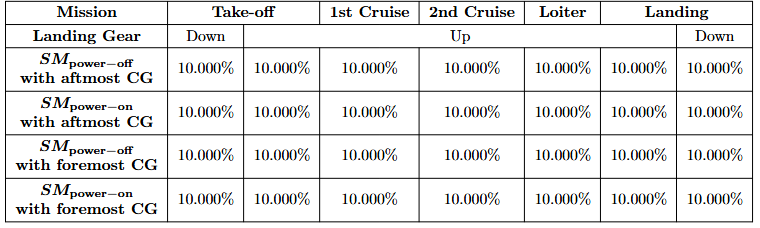

SM_off_aft * 100

ans =    80.1570   77.1499   79.2560   71.1127   67.4026   77.6667   80.6739


SM_on_aft = SM_off_aft  - 0.02;
SM_on_aft * 100

ans =    78.1570   75.1499   77.2560   69.1127   65.4026   75.6667   78.6739



SM_off_for * 100

ans =    84.0808   84.2637   86.3698   78.2265   74.5165   84.7806   84.5976


SM_on_for = SM_off_for  - 0.02;
SM_on_for * 100

ans =    82.0808   82.2637   84.3698   76.2265   72.5165   82.7806   82.5976


## 3. Trim Analysis

 